## SIOT Data Analysis

This live script gets the syncronized track features, session features and local/global moods from the .csv file, then performs some time frequency analysis.

%% Import data from text file
% Script for importing data from the following text file:
%
%    filename: C:\Users\Luke Hillery\Documents\DE4\IoT\Coursework\u_ok_hun report\u_okay_hun-results.csv
%
% Auto-generated by MATLAB on 13-Jan-2021 12:22:37

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 28);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["datetime", "entry", "playing", "genre", "raw_tempo", "raw_danceability", "raw_valence", "raw_energy", "session_tempo", "session_danceability", "session_valence", "session_energy", "gb_tempo", "gb_tempo_dev", "gb_dance", "gb_dance_dev", "gb_valence", "gb_valence_dev", "gb_energy", "gb_energy_dev", "global_tempo", "global_tempo_dev", "global_danceability", "global_danceability_dev", "global_valence", "global_valence_dev", "global_energy", "global_energy_dev"];
opts.VariableTypes = ["char", "double", "double", "char", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["datetime", "genre"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["datetime", "genre"], "EmptyFieldRule", "auto");

% Import the data
uokayhunresults = readtable("C:\Users\Luke Hillery\Documents\DE4\IoT\Coursework\u_ok_hun report\u_okay_hun-results.csv", opts);

%% Convert to output type
uokayhunresults = table2cell(uokayhunresults);
numIdx = cellfun(@(x) ~isnan(str2double(x)), uokayhunresults);
uokayhunresults(numIdx) = cellfun(@(x) {str2double(x)}, uokayhunresults(numIdx));

%% Clear temporary variables
clear opts


Next, each variable column is isolated and named:

datetime = uokayhunresults(:,1);

raw_tempo = uokayhunresults(:,5);
raw_danceability = uokayhunresults(:,6);
raw_valence = uokayhunresults(:,7);
raw_energy = uokayhunresults(:,8);

session_tempo = uokayhunresults(:,9);
session_danceability = uokayhunresults(:,10);
session_valence = uokayhunresults(:,11);
session_energy = uokayhunresults(:,12);

gb_tempo = uokayhunresults(:,13);
gb_danceability = uokayhunresults(:,15);
gb_valence = uokayhunresults(:,17);
gb_energy = uokayhunresults(:,19);
gb_concat = [gb_tempo,gb_danceability,gb_valence,gb_energy];

global_tempo = uokayhunresults(:,21);
global_danceability = uokayhunresults(:,23);
global_valence = uokayhunresults(:,25);
global_energy = uokayhunresults(:,27);
global_concat = [global_tempo,global_danceability,global_valence,global_energy];

Convert each block of data into arrays for easier processing.

datetime = cell2mat(uokayhunresults(:,1));
raw_results = cell2mat(uokayhunresults(:,5:8));
session_results = cell2mat(uokayhunresults(:,9:12));
gb_results = cell2mat(gb_concat);
global_results = cell2mat(global_concat);



 Replace NaN values with zeroes.

raw_results(isnan(raw_results))=0;
session_results(isnan(session_results))=0;
gb_results(isnan(gb_results))=0;
global_results(isnan(global_results))=0;

Raw Data Visualisation:

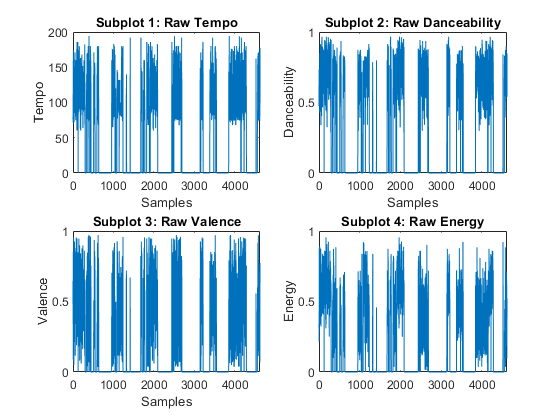

figure
subplot(2,2,1);
plot(raw_results(:,1))
title('Subplot 1: Raw Tempo')

subplot(2,2,2);
plot(raw_results(:,2))
title('Subplot 2: Raw Danceability')

subplot(2,2,3);
plot(raw_results(:,3))
title('Subplot 3: Raw Valence')

subplot(2,2,4);
plot(raw_results(:,4))
title('Subplot 4: Raw Energy')

subplot(2,2,1)
xlabel('Samples')
ylabel('Tempo')
subplot(2,2,2)
xlabel('Samples')
ylabel('Danceability')
subplot(2,2,3)
xlabel('Samples')
ylabel('Valence')
subplot(2,2,4)
ylabel('Energy')

Session Data Visualisation:

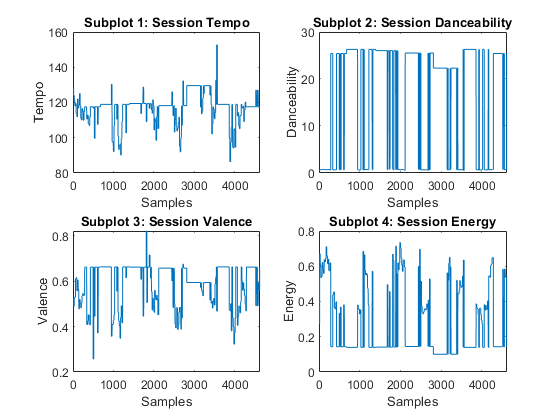

figure
title('Session Data Visualisation')

subplot(2,2,1);
plot(session_results(:,1))
title('Subplot 1: Session Tempo')

subplot(2,2,2);
plot(session_results(:,2))
title('Subplot 2: Session Danceability')

subplot(2,2,3);
plot(session_results(:,3))
title('Subplot 3: Session Valence')

subplot(2,2,4);
plot(session_results(:,4))
title('Subplot 4: Session Energy')

subplot(2,2,1)
xlabel('Samples')
ylabel('Tempo')
subplot(2,2,2)
xlabel('Samples')
ylabel('Danceability')
subplot(2,2,3)
xlabel('Samples')
ylabel('Valence')
subplot(2,2,4)
xlabel('Samples')
ylabel('Energy')

Track Feature Correlation

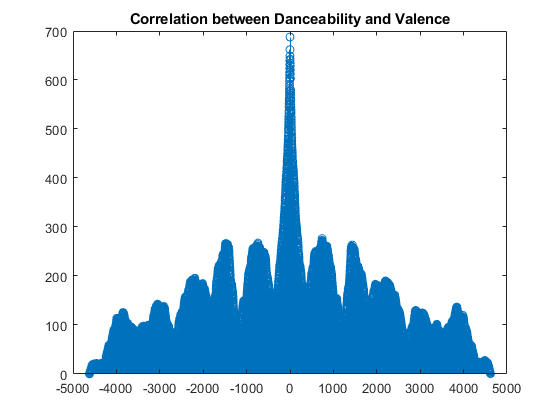

figure
[c,lags] = xcorr(raw_results(:,2),raw_results(:,3));
stem(lags,c)
title('Correlation between Danceability and Valence')

Partial Autocorrelation

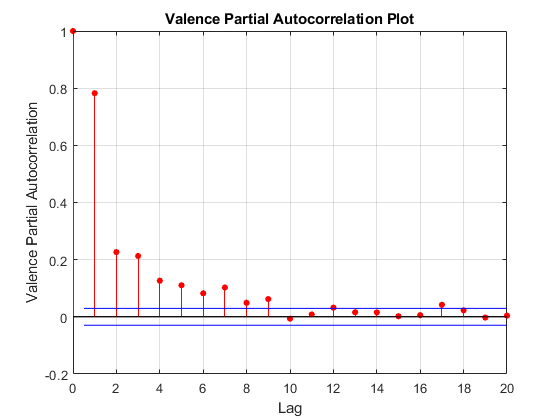

figure
parcorr(raw_results(:,3))
title('Valence Partial Autocorrelation Plot')
ylabel('Valence Partial Autocorrelation')

Autocorrelation

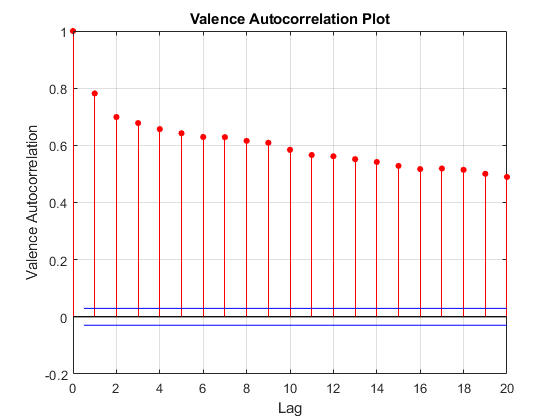

figure
autocorr(raw_results(:,3))
title('Valence Autocorrelation Plot')
ylabel('Valence Autocorrelation')

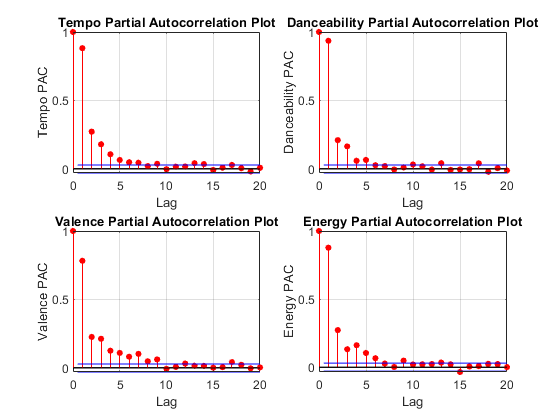


figure
title('Raw Data Partial Autocorrelation')

subplot(2,2,1);
parcorr(raw_results(:,1))
title('Tempo Partial Autocorrelation Plot')
ylabel('Tempo PAC')

subplot(2,2,2);
parcorr(raw_results(:,2))
title('Danceability Partial Autocorrelation Plot')
ylabel('Danceability PAC')

subplot(2,2,3);
parcorr(raw_results(:,3))
title('Valence Partial Autocorrelation Plot')
ylabel('Valence PAC')

subplot(2,2,4);
parcorr(raw_results(:,4))
title('Energy Partial Autocorrelation Plot')
ylabel('Energy PAC')

Scatter Matrix for raw data:

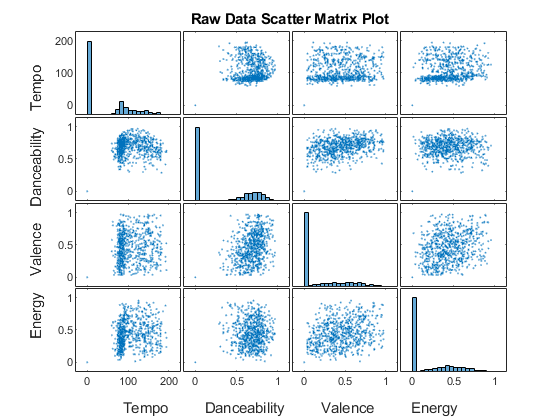

figure 
plotmatrix(raw_results)
title('Raw Data Scatter Matrix Plot')
% axes 17
xlabel('Tempo         Danceability         Valence         Energy')
% axes 20
ylabel('Energy    Valence    Danceability    Tempo')

Scatter Matrix for session data:

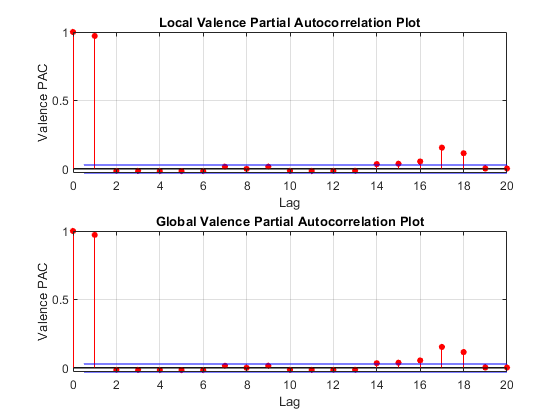

figure
subplot(2,1,1);
parcorr(gb_results(:,3))
title('Local Valence Partial Autocorrelation Plot')
ylabel('Valence PAC')

subplot(2,1,2);
parcorr(global_results(:,3))
title('Global Valence Partial Autocorrelation Plot')
ylabel('Valence PAC')